%this project just does what you did in your initial project, with the
%addition of the option of adding that cross to ignore traces which are
%close to the borders between quadrants. As both options are included, you
%can't run the whole thing at once. If you wish to use the cross you use
%those sections, while ignoring those that don't use the cross, and vice
%verca.
expmt.data.time

ans =   RawDataField with properties:

          raw: [0×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/DATA/test_data/vinegar_test_air/Or83b[2]/virgins/vinegar_post_control/11-12-2021-11-31-39__Basic_Tracking_1-1_Day1/raw_data/11-12-2021-11-31-39__time.bin'
          fID: 4
          dim: [1 1]
    precision: 'single'


reset(expt.data.time)

ans =   9598×1 RawDataField array with properties:

          raw: [9598×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/DATA/test_data/vinegar_test_air/Or83b[2]/virgins/vinegar_post_control/11-12-2021-11-31-39__Basic_Tracking_1-1_Day1/raw_data/11-12-2021-11-31-39__time.bin'
          fID: 4
          dim: [9598 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1


interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw();

a = expmt.meta.roi

a = struct with fields:
           mode: 'grid'
          shape: {'Quadrilateral'}
            vec: [1×4×2 double]
            row: 1
            col: 1
           grid: 1
        corners: [35.0946 21.2568 983.5187 983.5187]
         bounds: [35.0946 21.2568 948.4241 962.2620]
        centers: [504.2505 502.3877]
    orientation: 0
          tform: {[]}
             im: [1024×1024 uint8]
              n: 1
         pixIdx: {[925460×1 double]}
           mask: [1024×1024 logical]
     num_traces: 5
       cam_dist: 711.0948


xcentre = (a.centers(1,1))

xcentre = 504.2505

ycentre = (a.centers(1,2)) %reads out centres of the ROI

ycentre = 502.3877

out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:})

out = 47990×2 single matrix
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
  157.8197  149.3607
  157.8175  149.3968
  156.5159  148.7619
  152.9923  146.9462
  146.2571  141.3214
  138.2857  133.4429


%Unsure why, in one or two runs the xcentre and ycentre values are
%completely wrong. Here I manually set them to 512 or thereabouts when that
%was the case
%xcentre=512
%ycentre=512

%asigning quadrants to each point
% x = out(:, 1);
% y = out(:, 2);
% 
% out(x>=xcentre & y>=ycentre,3) = 1;
% out(x<=xcentre & y>=ycentre,3) = 2;
% out(x<=xcentre & y<=ycentre,3) = 3;
% out(x>=xcentre & y<=ycentre,3) = 4;

%asigning quadrants to each point with the added cross of points we are
%excluding from the data
x = out(:, 1);
y = out(:, 2);

out(x>xcentre+50 & y>ycentre+50,3) = 1;
out(x<xcentre-50 & y>ycentre+50,3) = 2;
out(x<xcentre-50 & y<ycentre-50,3) = 3;
out(x>xcentre+50 & y<ycentre-50,3) = 4;

out(x>xcentre-50 & x<xcentre+50,3) = 0; 
out(y>ycentre-50 & y<ycentre+50,3) = 0;


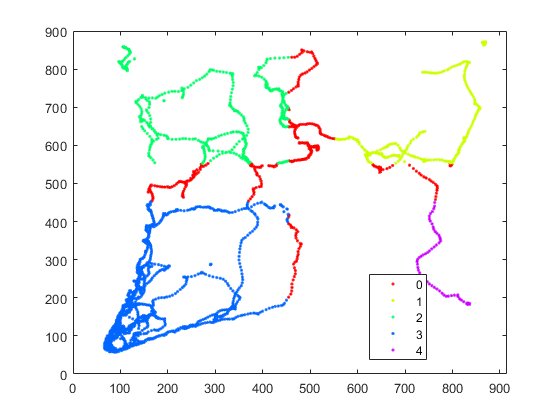

%Convert to table
T = array2table(out);

%Remove NaNs

T=T(~any(ismissing(T),2),:);

gscatter(T.out1, T.out2, T.out3)

saveas(gca, "C:\Users\Jefferis Group\Documents\GitHub\margo_data\DATA\test_data\vinegar_test_air\Or83b[2]\virgins\vinegar_post_control\11-12-2021-11-31-39__Basic_Tracking_1-1_Day1/quadrant", 'png')

%Attraction index for each quarter, without cross
% GC = groupcounts(T,'out3');
% C1 = table2array(GC(1,2));
% 
% 
% C2 = table2array(GC(2,2));   
% C3 = table2array(GC(3,2));  
% C4 = table2array(GC(4,2)); 
% AI1 = (C1-(C2+C3+C4)/3)/(C1+ (C2+C3+C4)/3);
% AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
% AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
% AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);

%Attraction index for each quarter with cross
GC = groupcounts(T,'out3');
C1 = table2array(GC(2,2));
C2 = table2array(GC(3,2));
C3 = table2array(GC(4,2));
C4 = table2array(GC(5,2));
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C4+C1)/3)/(C3+(C2+C4+C1)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);

AI = [AI1 AI2 AI3 AI4]

AI =    -0.1296   -0.7064    0.5875   -0.2076
